load('proj4Data.mat');

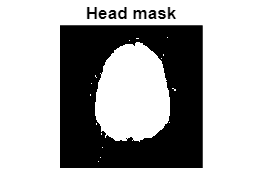

% Create head mask
t2_image = squeeze(anat_m(:,:,1));
t2Max = max(t2_image(:));
mask_m = (t2_image > 0.05*t2Max);
figure
imagesc(mask_m)
colormap(gray)
axis image
axis off
title('Head mask')

% index_v = find(mask_m(:));
% nHeadPixels = length(index_v);
% t2wHead_v = t2w_m(index_v);
% for pixel = 1:nHeadPixels
%     eigValues_3d(pixel,1)
% end

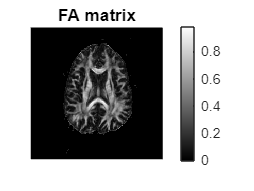

[nRows, nCols] = size(anat_m);

fa_m = zeros(nRows,nCols);
for row = 1:nRows
    for col = 1: nCols
        if (mask_m(row, col) == 1)
            lamda1 = eigValues_3d(row,col,1);
            lamda2 = eigValues_3d(row,col,2);
            lamda3 = eigValues_3d(row,col,3);
            lamda_mean = mean([lamda1,lamda2,lamda3]);

            fa_m(row, col) = sqrt(3/2.* ...
                ( (lamda_mean-lamda1).^2 + (lamda_mean-lamda2).^2 + (lamda_mean-lamda3).^2) / ...
                (lamda1.^2 + lamda2.^2 + lamda3.^2) ...
                ) ;
        end
    end
end 
grayScaleMap = mat2gray(fa_m);
imagesc(fa_m)
axis image
axis off
colorbar
title('FA matrix')

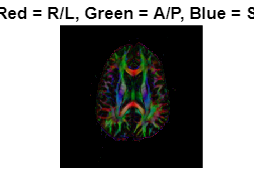

% Display color-coded FA map:
red_m = fa_m .* abs(fastDiffVector_3d(:, :, 1));
green_m = fa_m .* abs(fastDiffVector_3d(:, :, 2));
blue_m = fa_m .* abs(fastDiffVector_3d(:, :, 3));
color_3d = cat(3, red_m, green_m, blue_m);
imagesc(color_3d)
axis image
axis off
title('Red = R/L, Green = A/P, Blue = S/I')

imagesc(anat_m)
axis image
colormap(gray)
hold on
disp('Define seed point...')

Define seed point...


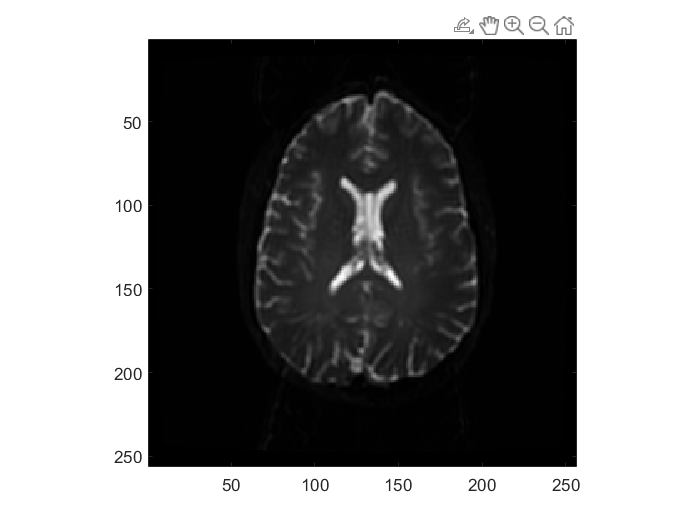

[x0, y0] = ginput(1);

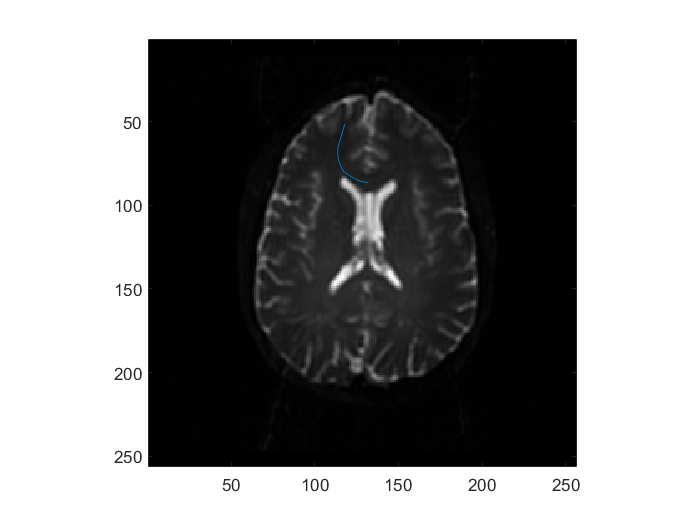

In-plane component of fast_v is too small


x = x0;
y = y0;
x_v = x0;
y_v = y0;
stepFlag = 1;
cosAngle = 1;
stepSize = 1;
while (stepFlag == 1)
    % Insert code here to find the fast diffusion direction at the nearest   
    % integer values of x and y:
    
    % We want to track fibers in the plane of the image, so insert code
    % here to find the component of the fast diffusion direction in the 
    % image plane. Call this fast_v (it should have just two elements,
    % the x and y components of the fast diffusion direction):
%     fast_3d = fastDiffVector_3d(round(y),round(x),:);
% 
%     fast_v = fast_3d(:,:,1:2) ;
    fast_v = [fastDiffVector_3d(round(y),round(x),1), ...
              fastDiffVector_3d(round(y),round(x),2)];
    % Break out of the while loop if the in-plane component of the 
    % vector is too small:
    if (sum(fast_v.^2) < 0.5)
        disp('In-plane component of fast_v is too small')
        break
    end
    
    % If this is not the first step away from the seed point, calculate
    % cosAngle, the cosine of the angle between the previous step and
    % fast_v. If cosAngle is negative, reverse the direction of fast_v
    if (length(x_v) > 1)
        cosAngle = dot(fast_v, prev_step_direction) / (norm(fast_v).*norm(prev_step_direction));
        if cosAngle < 0
            fast_v = -fast_v;
            print("Swap fast_v");
        end
    end
    prev_step_direction = fast_v;

    % Step a distance stepSize in the direction of fast_v 
    % (i.e., update x_v and y_v):
    x = x + stepSize.*fast_v(1);
    y = y + stepSize.*fast_v(2);     
    x_v(end+1) = x;
    y_v(end+1) = y;

    % Add a line segment to the image to show the current step:
    line([x_v(length(x_v)-1), x], [y_v(length(y_v)-1), y])
    drawnow
    
    % Add code here to set stepFlag = 0 if abs(cosAngle) is too small:
    if abs(cosAngle) < 0.1
        stepFlag = 0
    end 
% End of while loop:
end 

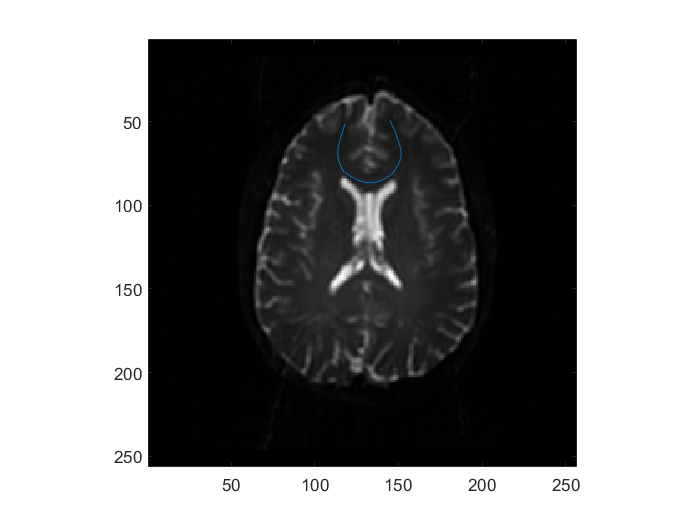

In-plane component of fast_v is too small


% opposite tracking 
x = x0;
y = y0;
x_opp_v = x0;
y_opp_v = y0;
stepFlag = 1;
cosAngle = 1;
stepSize = -1;
while (stepFlag == 1)
    % Insert code here to find the fast diffusion direction at the nearest   
    % integer values of x and y:
    
    % We want to track fibers in the plane of the image, so insert code
    % here to find the component of the fast diffusion direction in the 
    % image plane. Call this fast_v (it should have just two elements,
    % the x and y components of the fast diffusion direction):
%     fast_3d = fastDiffVector_3d(round(y),round(x),:);
% 
%     fast_v = fast_3d(:,:,1:2) ;
    fast_v = [fastDiffVector_3d(round(y),round(x),1), ...
              fastDiffVector_3d(round(y),round(x),2)];
    % Break out of the while loop if the in-plane component of the 
    % vector is too small:
    if (sum(fast_v.^2) < 0.5)
        disp('In-plane component of fast_v is too small')
        break
    end
    
    % If this is not the first step away from the seed point, calculate
    % cosAngle, the cosine of the angle between the previous step and
    % fast_v. If cosAngle is negative, reverse the direction of fast_v
    if (length(x_opp_v) > 1)
        cosAngle = dot(fast_v, prev_step_direction) / (norm(fast_v).*norm(prev_step_direction));
        if cosAngle < 0
            fast_v = -fast_v;
            print("Swap fast_v");
        end
    end
    prev_step_direction = fast_v;

    % Step a distance stepSize in the direction of fast_v 
    % (i.e., update x_v and y_v):
    x = x + stepSize.*fast_v(1);
    y = y + stepSize.*fast_v(2);     
    x_opp_v(end+1) = x;
    y_opp_v(end+1) = y;

    % Add a line segment to the image to show the current step:
    line([x_opp_v(length(x_opp_v)-1), x], [y_opp_v(length(y_opp_v)-1), y])
    drawnow
    
    % Add code here to set stepFlag = 0 if abs(cosAngle) is too small:
    if abs(cosAngle) < 0.1
        stepFlag = 0
    end 
% End of while loop:
end

hold off

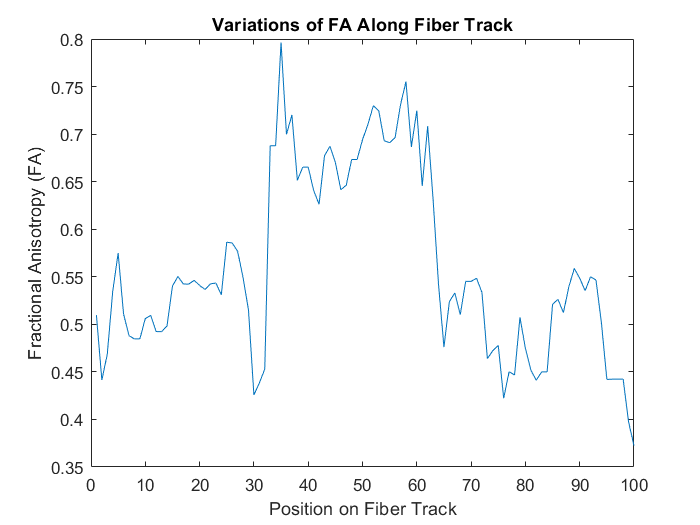

full_x_v = round([flip(x_v), x_opp_v]);
full_y_v = round([flip(y_v), y_opp_v]);

FA_vect = zeros(1,length(full_x_v)) ;

for i = 1:length(full_x_v)
    FA_vect(i) = fa_m(full_y_v(i),full_x_v(i)) ;
end

plot(FA_vect)

ylabel("Fractional Anisotropy (FA)")

xlabel("Position on Fiber Track")

title("Variations of FA Along Fiber Track")

% Plot FA wrt position
% CANT DO
% full_x_v = round([flip(x_v), x_opp_v])
% 
% full_y_v = round([flip(y_v), y_opp_v])
% plot(fa_m(full_y_v, full_x_v))